clear all
close all
clc
% Specify the wing image path
disp('Wing geometry in use');

Wing geometry in use


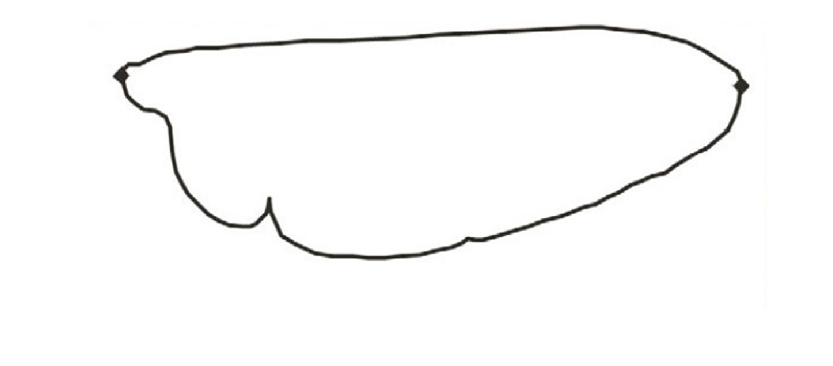

wingPath = "E:\Downloads\Drosophila_wings.png";

% Display the wing
imshow(wingPath);

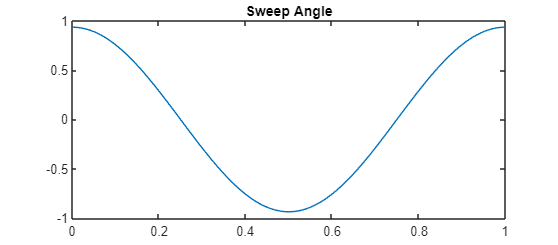


% Data required
rho = 1.2754;          % density of air in kg/m^3
b = 0.0112;             % m
Cmean = 0.00298;        % m
S = 3.3340e-05;
AR = 7.52;
x0_cap = 0.3;   % non-dimensionalise position of rotational axis
r2_cap=0.55;
I1=0.526;
I2=1.23;
delta_tr=0.3;
% Kinematics
phi_0 =0;
alpha_0=0;
k_phi = 0.1;  % shape parameter
%k_alpha=5;
phi_m = 53.55*pi/180;
alpha_m = 31.8 * pi / 180;
sweep_amplitude = phi_m / asin(k_phi);
inc_amplitude = (pi - 2*alpha_m) / delta_tr;
t = 0:0.001:1;
l = length(t);

t1=delta_tr/2;
t2=0.5-delta_tr/2;
t3=0.5+delta_tr/2;
t4=1-delta_tr/2;
sweep=zeros(1, l);  % Initializing sweep angle array
for i=1:l
    sweep(i) = sweepfunction(phi_0, sweep_amplitude, k_phi, t(i));
    if t(i)<t1
        alpha(i)=(inc_amplitude*(t(i)-delta_tr/(2*pi)*sin(2*pi*(t(i)+t1)/delta_tr)));
        alpha_dot(i)= inc_amplitude*(1-cos(2*pi*(t(i)+t1)/delta_tr));
        alpha_ddot(i)=inc_amplitude*2*pi/delta_tr*sin(2*pi*(t(i)+t1)/delta_tr);
    end

    if t(i)>=t1 && t(i)<t2
        alpha(i)=(pi/2-alpha_m);
        alpha_dot(i)=0;
        alpha_ddot(i)=0;
    end

    if t(i)>=t2 && t(i)<t3
        alpha(i)=(pi/2-alpha_m - inc_amplitude*((t(i)-t2)-delta_tr/(2*pi)*sin(2*pi*(t(i)-t2)/delta_tr)));
        alpha_dot(i)= -inc_amplitude*(1-cos(2*pi*(t(i)-t2)/delta_tr));
        alpha_ddot=-inc_amplitude*2*pi/delta_tr*sin(2*pi*(t(i)-t2)/delta_tr);
    end
    if t(i)>=t3 && t(i)<t4
        alpha(i)=(-pi/2+alpha_m);
        alpha_dot(i)=0;
        alpha_ddot(i)=0;
    end

    if t(i)>=t4
        alpha(i)=-pi/2+alpha_m+inc_amplitude*((t(i)-t4)-delta_tr/(2*pi)*sin(2*pi*(t(i)-t4)/delta_tr));
        alpha_dot(i)= inc_amplitude*(1-cos(2*pi*(t(i)-t4)/delta_tr));
        alpha_ddot(i)=inc_amplitude*2*pi/delta_tr*sin(2*pi*(t(i)-t4)/delta_tr);
    end
end
phi_dot = gradient(sweep, t(2)-t(1));
phi_ddot = gradient(phi_dot, t(2)-t(1));
plot(t, sweep);
title('Sweep Angle');

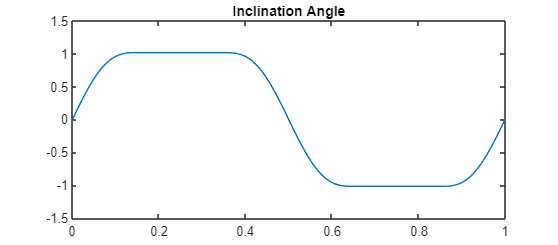

plot(t, alpha);
title('Inclination Angle');

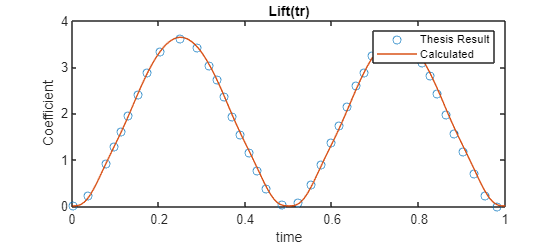






% Aerodynamic Calculations
U=4*phi_m*r2_cap*b;
U_cp = (r2_cap * b * phi_dot).^2;
l = length(t);
for i = 1:l
    C_n(i) = 3.4 * sin(pi / 2 - (alpha(i)));   
    if abs(pi/2-abs(alpha(i)))>=0 && abs(pi/2-abs(alpha(i)))<0.25*pi
        C_t(i)=0.4*(cos(2*(pi/2-abs(alpha(i)))))^2;
    end
    if abs(pi/2-abs(alpha(i)))>=0.25*pi && abs(pi/2-abs(alpha(i)))<0.75*pi
        C_t(i)=0;
    end
    if abs(pi/2-abs(alpha(i)))>=0.75*pi && abs(pi/2-abs(alpha(i)))<pi
        C_t(i)=-0.4*(cos(2*(pi/2-abs(alpha(i)))))^2;
    end
    Translational_Lift(i) = 0.5*rho*(C_n(i)*cos(pi/2-abs(alpha(i)))-C_t(i)*sin(pi/2-abs(alpha(i))))*S*b*b*r2_cap*r2_cap*phi_dot(i)^2;
    Translational_Drag(i) = 0.5*rho*(C_n(i)*sin(pi/2-abs(alpha(i)))+C_t(i)*cos(pi/2-abs(alpha(i))))*S*b*b*r2_cap*r2_cap*phi_dot(i)^2;
    

    % Rotational Forces
    Rotational_Lift(i) = pi*rho*(3/4 - x0_cap)*phi_dot(i)*alpha_dot(i)*I1*b^2*Cmean^2*cos(pi/2-abs(alpha(i)));
    Rotational_Drag(i) = pi*rho*(3/4 - x0_cap)*phi_dot(i)*alpha_dot(i)*I1*b^2*Cmean^2*sin(pi/2-abs(alpha(i)));

    % Added mass Forces
    Added_mass_Lift(i) = (-0.25*rho*pi*b^2*Cmean^2*(phi_ddot(i)*sin(pi/2-abs(alpha(i)))+phi_dot(i)*alpha_dot(i)*cos(pi/2-abs(alpha(i))))*I1+(1/16)*rho*pi*b*Cmean^3*alpha_ddot(i)*I2)*cos(pi/2-abs(alpha(i)));
    Added_mass_Drag(i) = (-0.25*rho*pi*b^2*Cmean^2*(phi_ddot(i)*sin(pi/2-abs(alpha(i)))+phi_dot(i)*alpha_dot(i)*cos(pi/2-abs(alpha(i))))*I1+(1/16)*rho*pi*b*Cmean^3*alpha_ddot(i)*I2)*sin(pi/2-abs(alpha(i)));
    
    %Total Forces
    Total_Lift(i)=Translational_Lift(i) + Rotational_Lift(i) + Added_mass_Lift(i);
    Total_Drag(i)=Translational_Drag(i) + Rotational_Drag(i) + Added_mass_Drag(i);
    % Coefficients
    Translational_Lift_Coefficient(i) = Translational_Lift(i) / (0.5 * rho * S * U.^2);
    Translational_Drag_Coefficient(i) = Translational_Drag(i) / (0.5 * rho * S * U.^2);
    Rotational_Lift_Coefficient(i)=(Translational_Lift(i)+Rotational_Lift(i))/ (0.5 * rho * S * U.^2);
    Rotational_Drag_Coefficient(i)=(Translational_Drag(i)+Rotational_Drag(i))/ (0.5 * rho * S * U.^2);
    Total_Lift_Coefficient(i) = (Total_Lift(i))/(0.5 * rho * S * U.^2);
    Total_Drag_Coefficient(i) = (Total_Drag(i))/(0.5 * rho * S * U.^2);
end


Array = csvread("C:\Users\MAYANK\OneDrive - Indian Institute of Technology Jodhpur\BET\Lift(tr).csv", 1, 0);

% Extract the columns
col1 = Array(:, 1);
col2 = Array(:, 2);

% Plot the data
plot(col1, col2, 'o');
hold on;

% Add title and axis labels
title('Lift(tr)');
xlabel('time');
ylabel('Coefficient');

plot(t,Translational_Lift_Coefficient);
title('Lift(tr)');
hold off;
%Add legends
legend('Thesis Result', 'Calculated');

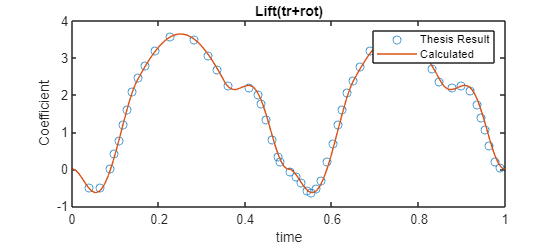

Array = csvread("C:\Users\MAYANK\OneDrive - Indian Institute of Technology Jodhpur\BET\Lift(tr+rot).csv", 1, 0);

% Extract the columns
col1 = Array(:, 1);
col2 = Array(:, 2);

% Plot the data
plot(col1, col2, 'o');
hold on;

% Add title and axis labels
title('Lift(tr+rot)');
xlabel('time');
ylabel('Coefficient');

plot(t, Rotational_Lift_Coefficient);
hold off;

% Add legends
legend('Thesis Result', 'Calculated');

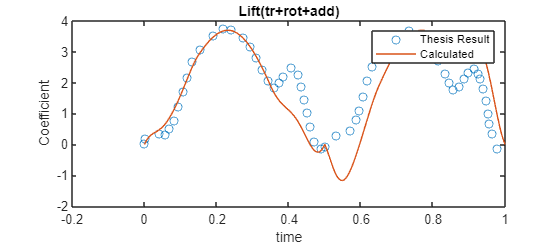

Array = csvread("C:\Users\MAYANK\OneDrive - Indian Institute of Technology Jodhpur\BET\Lift(tr+rot+add).csv", 1, 0);

% Extract the columns
col1 = Array(:, 1);
col2 = Array(:, 2);

% Plot the data
plot(col1, col2, 'o');
hold on;

% Add title and axis labels
title('Lift(tr+rot+add)');
xlabel('time');
ylabel('Coefficient');

plot(t, Total_Lift_Coefficient);
hold off;

% Add legends
legend('Thesis Result', 'Calculated');

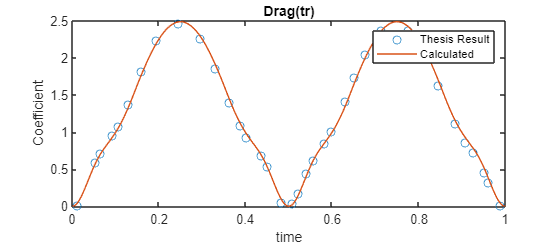

Array = csvread("C:\Users\MAYANK\OneDrive - Indian Institute of Technology Jodhpur\BET\Drag(tr).csv", 1, 0);

% Extract the columns
col1 = Array(:, 1);
col2 = Array(:, 2);

% Plot the data
plot(col1, col2, 'o');
hold on;

% Add title and axis labels
title('Drag(tr)');
xlabel('time');
ylabel('Coefficient');

plot(t,Translational_Drag_Coefficient);
hold off;
% Add legends
legend('Thesis Result', 'Calculated');

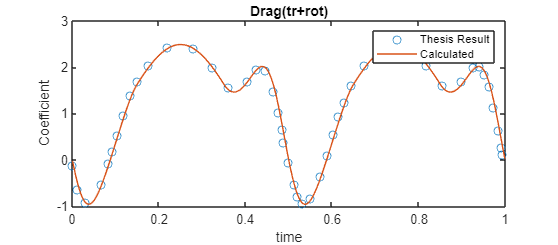

Array = csvread("C:\Users\MAYANK\OneDrive - Indian Institute of Technology Jodhpur\BET\Drag(tr+rot).csv", 1, 0);

% Extract the columns
col1 = Array(:, 1);
col2 = Array(:, 2);

% Plot the data
plot(col1, col2, 'o');
hold on;

% Add title and axis labels
title('Drag(tr+rot)');
xlabel('time');
ylabel('Coefficient');

plot(t,Rotational_Drag_Coefficient);
hold off;
% Add legends
legend('Thesis Result', 'Calculated');

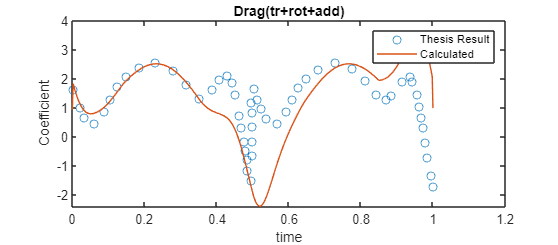

Array = csvread("C:\Users\MAYANK\OneDrive - Indian Institute of Technology Jodhpur\BET\Drag(tr+rot+add).csv", 1, 0);

% Extract the columns
col1 = Array(:, 1);
col2 = Array(:, 2);

% Plot the data
plot(col1, col2, 'o');
hold on;

% Add title and axis labels
title('Drag(tr+rot+add)');
xlabel('time');
ylabel('Coefficient');

plot(t, Total_Drag_Coefficient);
hold off;

% Add legends
legend('Thesis Result', 'Calculated');

function result = sweepfunction(phi_0, sweep_amplitude, k_phi, t)
    result = phi_0 + sweep_amplitude * asin(k_phi * cos(2 * pi * t));
end



